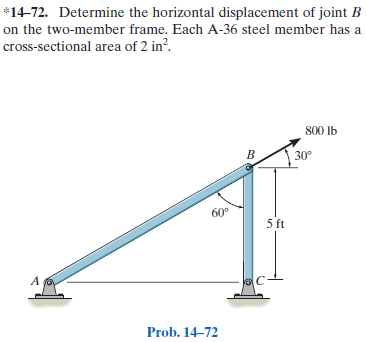

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-72P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-72P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = 30*u.deg;
jointA = [0 0]*u.ft;
jointB = 5*[cot(theta) 1]*u.ft;
jointC = 5*[cot(theta) 0]*u.ft;

# member data

E = 29e3*u.ksi;
A = 2*u.in^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('concentrated', 'Pb', 800*[cos(theta) sin(theta)]*u.lbf, jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0.001911\,\mathrm{in}\\ \mathrm{vB} & 0\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & 800\,\mathrm{lbf}\\ \mathrm{Fbc} & 0 \end{array}\right)$$

la_f_c_vpa = vpa(la.f.c, 5) %#ok<NASGU> 

$$la\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Ra} & -692.82\,\mathrm{lbf} & -400.0\,\mathrm{lbf} & 0\\ \mathrm{Rc} & 0 & 0 & 0\\ \mathrm{Pb} & 692.82\,\mathrm{lbf} & 400.0\,\mathrm{lbf} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c, 5) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 692.82\,\mathrm{lbf} & 400.0\,\mathrm{lbf} & 0\\ \mathrm{Fbc} & 0 & 0 & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & 800\,\mathrm{lbf}\\ \mathrm{Rc} & 0\\ \mathrm{Pb} & 800\,\mathrm{lbf} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rc} & 0 & 0 & 0\\ \mathrm{Pb} & 0 & 0 & 0 \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rc} & 0\\ \mathrm{Pb} & 0 \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m la_f_c_vpa ma_f_c_vpa la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;